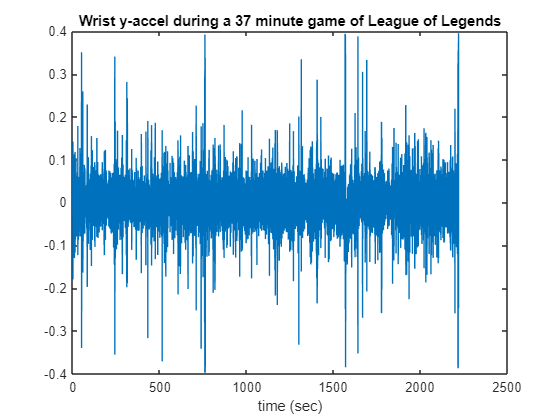

clear all;
data = csvread('LOL1_37min.csv',5);


ty = [data(:,2),data(:,4)];

ty(abs(ty(:,2))>0.4,:) = [];

t = ty(:,1);
y = ty(:,2);


figure()
plot(ty(:,1),ty(:,2))
title("Wrist y-accel during a 37 minute game of League of Legends");
xlabel('time (sec)')

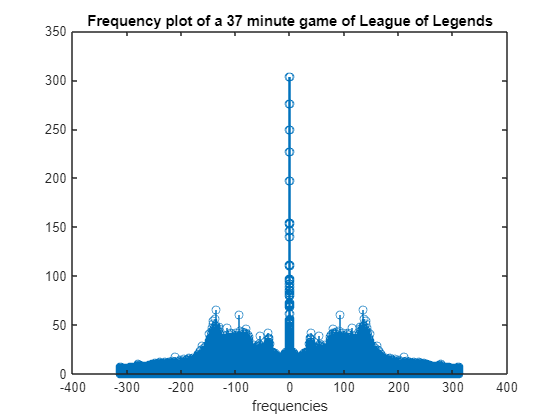



fourier = fftshift(fft(y));

N = length(y);
Fs = 1/(t(2) - t(1));
low = (-pi+(pi/N))*Fs;
high = (pi-(pi/N))*Fs;
frequencies_shifted = linspace(low, high, N)';

figure()
stem(frequencies_shifted,abs(real(fourier)))
title("Frequency plot of a 37 minute game of League of Legends");
xlabel('frequencies')

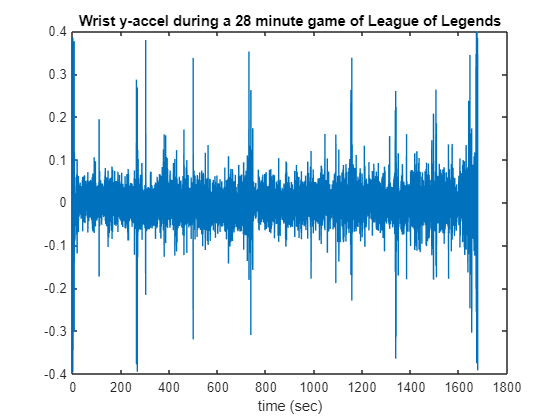

clear all;
data = csvread('LOL2_28min.csv',5);


ty = [data(:,2),data(:,4)];

ty(abs(ty(:,2))>0.4,:) = [];

t = ty(:,1);
y = ty(:,2);


figure()
plot(ty(:,1),ty(:,2))
title("Wrist y-accel during a 28 minute game of League of Legends");
xlabel('time (sec)')

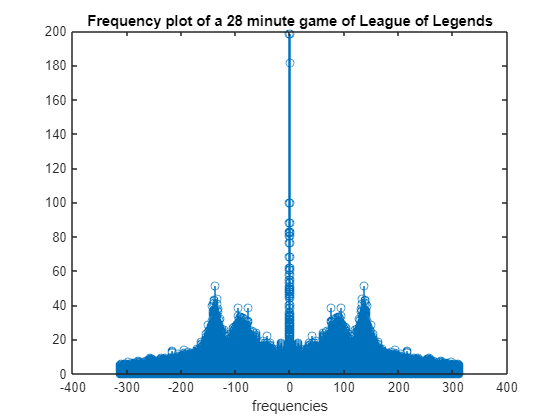



fourier = fftshift(fft(y));

N = length(y);
Fs = 1/(t(2) - t(1));
low = (-pi+(pi/N))*Fs;
high = (pi-(pi/N))*Fs;
frequencies_shifted = linspace(low, high, N)';

figure()
stem(frequencies_shifted,abs(real(fourier)))
title("Frequency plot of a 28 minute game of League of Legends");
xlabel('frequencies')